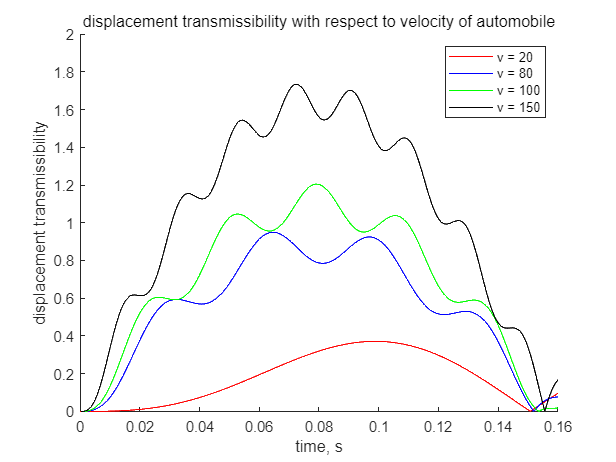

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 비감쇠 모델의 자동차가 과속방지턱을 넘어갈 때
% 자동차 속도에 대한 자동차 질량의 최대 상대변위의 관계식을 구하라

clear; clc;
k = 4*10^5; m  = 1007;
v = [20, 80, 100, 150];
Wn = sqrt(k/m); Wb = v.*(2*pi)/(0.0008*3600);
Y = 0.1; t = 0:0.0001:1;

% relative displacement with respect to velocity
Zp(1,:) = abs(Wb(1,1)^2*Y/(Wn*(Wn^2-Wb(1,1)^2))*(Wb(1,1)*sin(Wn*t)-Wn*sin(Wb(1,1)*t)));
Zp(2,:) = abs(Wb(1,2)^2*Y/(Wn*(Wn^2-Wb(1,2)^2))*(Wb(1,2)*sin(Wn*t)-Wn*sin(Wb(1,2)*t)));
Zp(3,:) = abs(Wb(1,3)^2*Y/(Wn*(Wn^2-Wb(1,3)^2))*(Wb(1,3)*sin(Wn*t)-Wn*sin(Wb(1,3)*t)));
Zp(4,:) = abs(Wb(1,4)^2*Y/(Wn*(Wn^2-Wb(1,4)^2))*(Wb(1,4)*sin(Wn*t)-Wn*sin(Wb(1,4)*t)));

hold on
plot(t, Zp(1,:), 'r')
title('displacement transmissibility with respect to velocity of automobile');
xlabel('time, s');
ylabel('displacement transmissibility');

plot(t, Zp(2,:), 'b')
plot(t, Zp(3,:), 'g')
plot(t, Zp(4,:), 'k')
legend('v = 20', 'v = 80', 'v = 100', 'v = 150');
axis([0, 0.16, 0, 2]);
hold off